clear; clear path; clc;
cd('~/git/hardDiskControl/continuousTimeControl/distReject/')
load('../../data/plantTF.mat');
addpath ../../funcs/;
format shortG

approximate zoh plant

riseTime = 0.022295; %seconds
Ts = riseTime/10;
% Psz = Ps*exp(-Ts/2);
Psz = Ps;

we now tune a contiunous pid on the continuous estimator of zoh plant

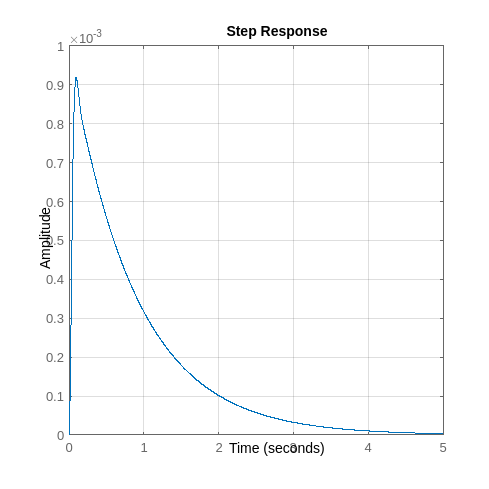

P = 1100;
I = 1200;
D = 40;
N = 120;
Csz = pidGen(P,I,D,N,1);

figure('Position',[0 0 1000 1000]); clf; hold on;
step(Psz/(1+Psz*Csz)); grid on;

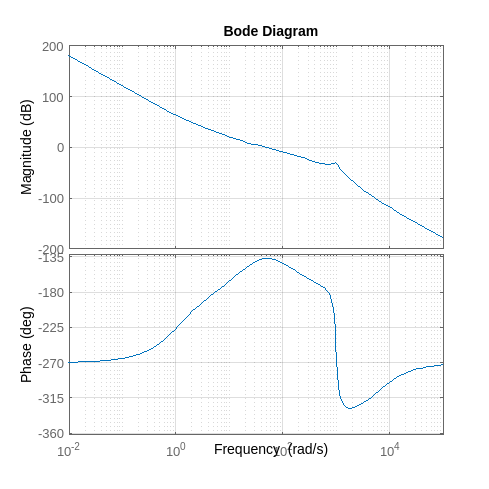


figure('Position',[0 0 1000 1000]); clf; hold on;
bode(Csz*Psz); grid on;

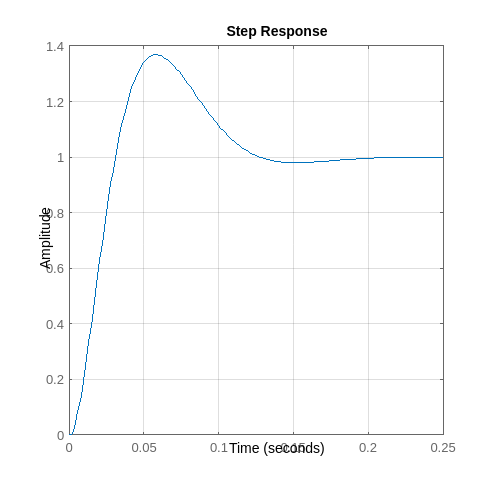


figure('Position',[0 0 1000 1000]); clf; hold on;
step(Csz*Psz/(1+Psz*Csz)); grid on;

we will now fix the input gain saturation

uMax = max(step(Csz*Psz/(1+Csz*Psz)))

uMax =        1.3682


if uMax>=200
    Csz = pidGen(P,I,D,N,200/uMax);
end

figure('Position',[0 0 1000 1000]); clf; hold on;
step(Psz/(1+Csz*Psz)); grid on;


figure('Position',[0 0 1000 1000]); clf; hold on;
bode(Csz*Psz); grid on;

We will now get the actual discrete system

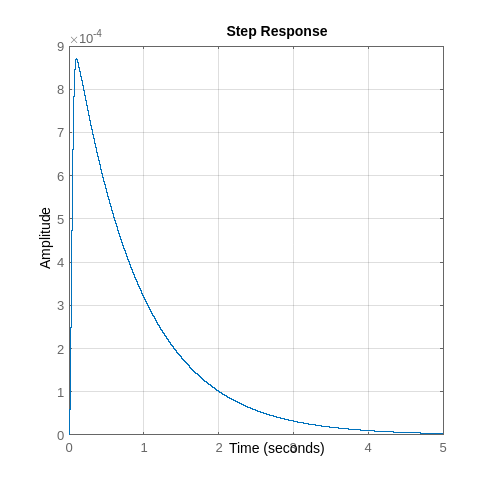

Pz = c2d(Ps,Ts);
Cz = c2d(Csz,Ts);

figure('Position',[0 0 1000 1000]); clf; hold on;
step(Pz/(1+Cz*Pz)); grid on;

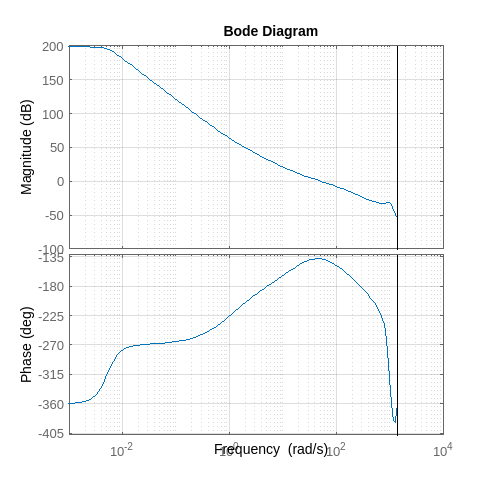


figure('Position',[0 0 1000 1000]); clf; hold on;
bode(Cz*Pz); grid on;

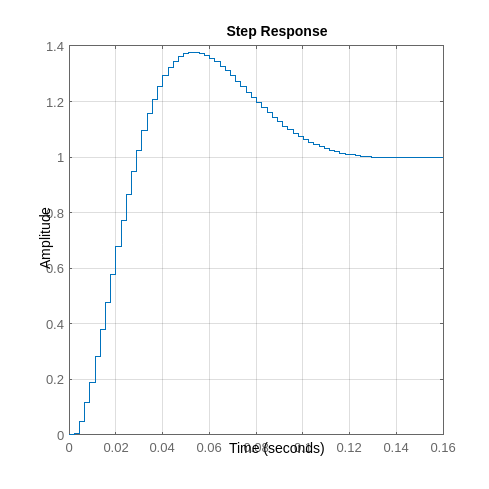


figure('Position',[0 0 1000 1000]); clf; hold on;
step(Cz*Pz/(1+Cz*Pz)); grid on;